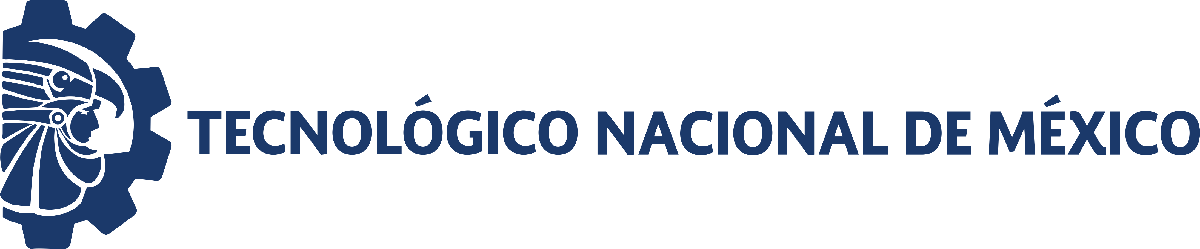                                 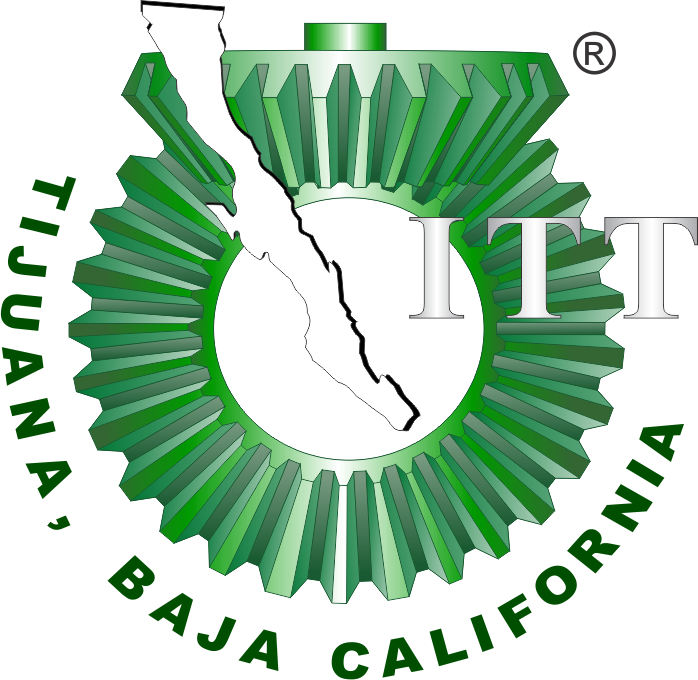

# Práctica: Regeneracion de globulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

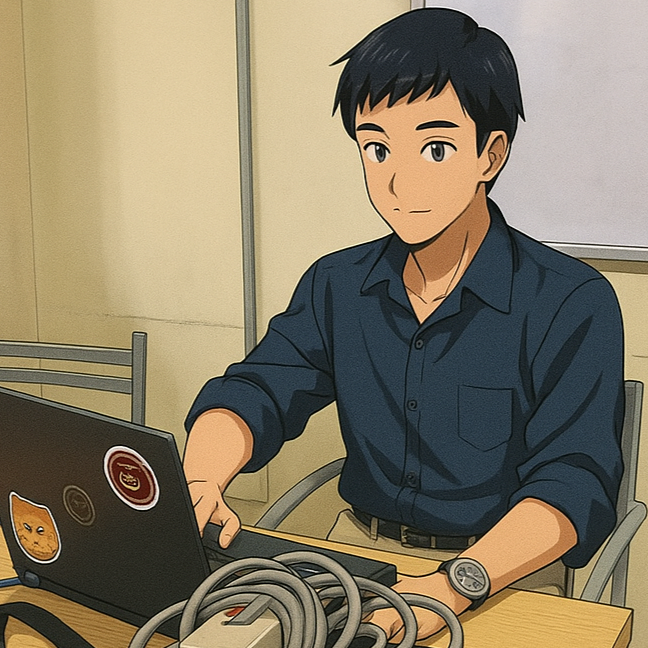

Nombre del alumno: Porfirio Emmanuel Ramirez Barajas

Número de control: 22211763

Correo institucional: L22211763**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all');
tend = 180; %Tiempo de simulacion en dias
dt = 1E-3; %Intervalo de integracion para el metodo de solucion por diferencias finitas
n = round(tend/dt) %Cantidad de iteraciones para el metodo numerico

n = 180000


%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44, x3_0 = 885; 

x2_0 = 44


%Parametros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057]; 
 beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

 seed = 22211763; %Semilla para asegurar reproducibilidad
 rng(seed, 'twister')

 %Intervalo de las condiciones iniciales
 xmin = 0.99; xmax = 1.01;
 interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

 %COndiciones iniciales para cada paciente
 x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
 x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
 x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');...



## Caso: Sin transfucion sanguinea [u(t) = 0]

 u = zeros(n+1,1); %No hay transfucion

x1(0) = 
   59.3284   59.2479   58.4946   59.2028   59.2068   58.8721   59.2406   59.5204   58.7726   58.5303



x2(0) = 
   44.2449   44.1849   43.6231   44.1512   44.1543   43.9046   44.1794   44.3881   43.8304   43.6497



x3(0) = 
  889.9253  888.7189  877.4187  888.0417  888.1027  883.0813  888.6089  892.8063  881.5885  877.9539



 fig = 1;
 for i = 1:10
 [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
 plotdata(t,x1,x2,x3,fig)
 end

## Caso: Transfusion sanguinea [u(t) = [t1,t2]]

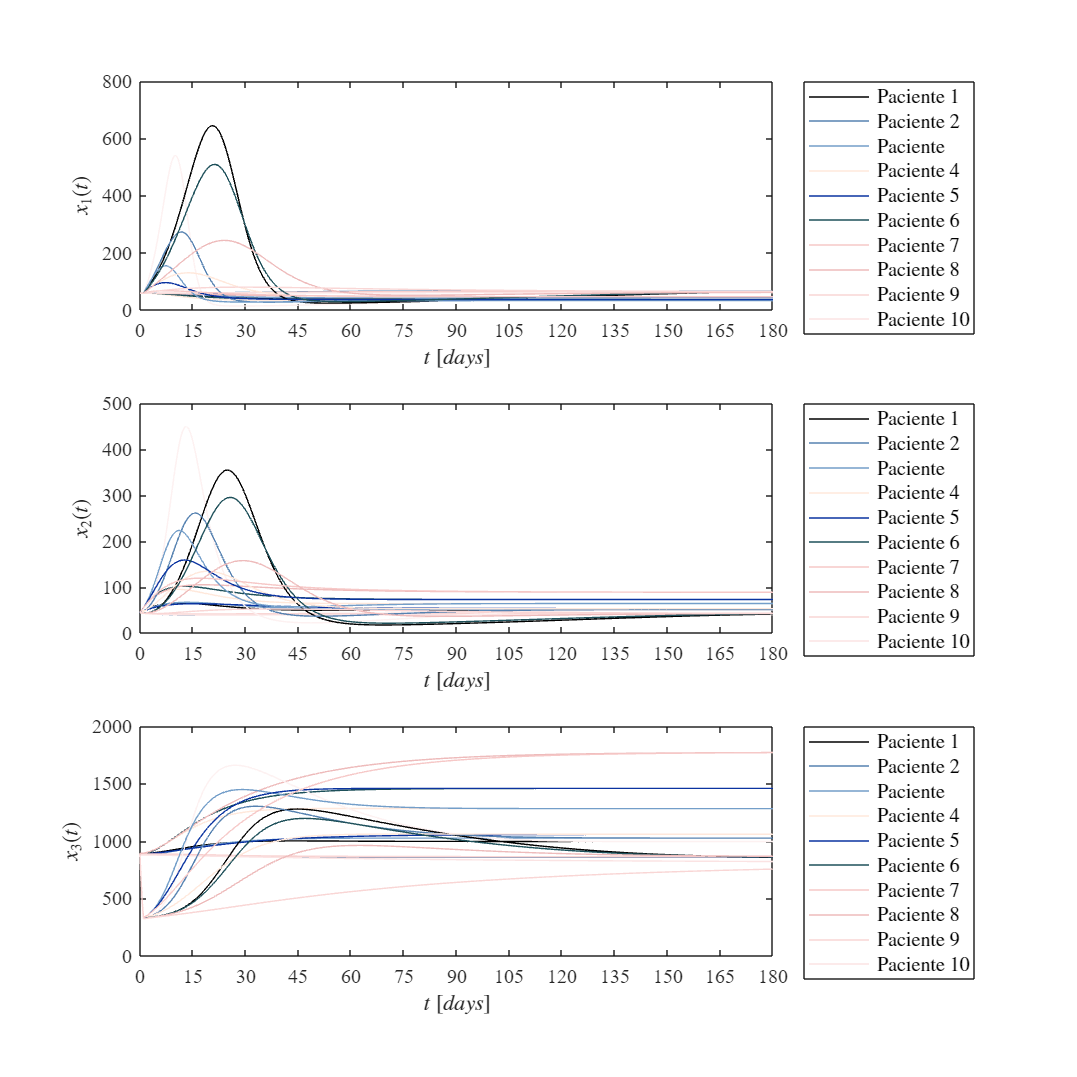

 fig = 2;
 u = zeros(n+1,1);
 u(1:1000)=1;

 for i = 1:10
 [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
 plotdata(t,x1,x2,x3,fig)
 end

## Funcion: Modelo matematico


$$\dot{x_1 =\beta \left(x_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }}$$



$$\dot{x_2 =\beta \left(k_1 x_1 -k_2 -x_2 \right)}$$



$$\dot{x_3 =\beta \left(k_2 x_2 -{\alpha x}_3 \right)-u\left(t\right)x_3 }$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    %Parametros fijos del sistema
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round(tend/dt);
    x1 = zeros(n+1,1); x1(1) = x1_0;
    x2 = zeros(n+1,1); x2(1) = x2_0;
    x3 = zeros(n+1,1); x3(1) = x3_0;

    for i = 1:n %Metodo de euler (diferencias finitas)
        x1(i+1) = x1(i) + (beta*(X0-k1*x1(i))+gamma*(Base-x3(i))*(1-u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i)-k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i)-alpha*x3(i))-u(i)*x3(i))*dt;
    end    
end

## Funcion: Soluciones en el tiempo

function plotdata(t, x1,x2, x3,fig)
    set(figure(fig), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters','Position', [1, 1,20, 20] )
     mycolors= [0,0,0;
        86,130,177;
        115,158,201;
        255,232,219;
        10, 51, 160
        30, 80, 90;
        246, 200, 199;
        238, 187, 187;
        249,214, 213;
        251, 227, 227;
        253, 241, 241]/255;
    colororder(mycolors)

    subplot (3,1,1)
    hold on; grid off; box on; colororder(mycolors);
    plot (t, x1)
    ylabel ('$x_1(t)$', 'Interpreter', 'latex', 'FontSize', 10)
    xlabel ('$t$ $[days]$', 'Interpreter', 'latex', 'FontSize', 10)
    xlim ([0 180]); xticks (0: 15:180)
    L= legend ('Paciente 1','Paciente 2', 'Paciente ', 'Paciente 4', 'Paciente 5', 'Paciente 6', 'Paciente 7', 'Paciente 8', 'Paciente 9', 'Paciente 10');
    set (L, 'Interpreter','Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    set (gca, 'FontName', 'Times New Roman', 'FontSize', 10)

    subplot (3,1,2)
    hold on; grid off; box on;colororder(mycolors);
    plot (t, x2)
    ylabel ('$x_2(t)$', 'Interpreter', 'latex', 'FontSize', 10)
    xlabel ('$t$ $[days]$', 'Interpreter', 'latex', 'FontSize', 10)
    xlim ([0 180]); xticks (0: 15:180)
    L= legend ('Paciente 1','Paciente 2', 'Paciente ', 'Paciente 4', 'Paciente 5', 'Paciente 6', 'Paciente 7', 'Paciente 8', 'Paciente 9', 'Paciente 10');
    set (L, 'Interpreter','Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    set (gca, 'FontName', 'Times New Roman', 'FontSize', 10)

    subplot (3,1,3)
    hold on; grid off; box on; colororder(mycolors); 
    plot (t, x3)
    ylabel ('$x_3(t)$', 'Interpreter', 'latex', 'FontSize', 10)
    xlabel ('$t$ $[days]$', 'Interpreter', 'latex', 'FontSize', 10)
    xlim ([0 180]); xticks (0: 15:180)
    L= legend ('Paciente 1','Paciente 2', 'Paciente ', 'Paciente 4', 'Paciente 5', 'Paciente 6', 'Paciente 7', 'Paciente 8', 'Paciente 9', 'Paciente 10');
    set (L, 'Interpreter','Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    set (gca, 'FontName', 'Times New Roman', 'FontSize', 10)

    if fig == 1
        exportgraphics (gcf, 'Caso sin transfusion.pdf','ContentType','vector')
    elseif fig == 2
        exportgraphics (gcf, 'Caso con transfusion.pdf','ContentType','vector')
    end
end